Practica 1B: Reconocimiento de letras y d´ıgitos mediante el An´alisis de Componentes Principales (PCA)

trainImagesFile = 'train-images.idx3-ubyte';
trainLabelsFile = 'train-labels.idx1-ubyte';
testImagesFile = 't10k-images.idx3-ubyte';
testLabelsFile = 't10k-labels.idx1-ubyte';


XTrain = processImagesMNIST(trainImagesFile);


Read MNIST image data...
Number of images in the dataset:  60000 ...


YTrain = processLabelsMNIST(trainLabelsFile);


Read MNIST label data...
Number of labels in the dataset:  60000 ...


XTest = processImagesMNIST(testImagesFile);


Read MNIST image data...
Number of images in the dataset:  10000 ...


YTest = processLabelsMNIST(testLabelsFile);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


1 Introducci´on 

Durante la pr´actica anterior, se ha implementado el algoritmo de las componentes principales (PCA) y se ha aplicado en el reconocimiento de im´agenes del conjunto de datos MNIST. En este caso, siendo una pr´actica introductoria, ´unicamente se ha realizado la resoluci´on de un problema de clasificaci´on binaria (dos clases, en este caso eran la clase “0” y la clase “5”). En esta pr´actica vamos a realizar distintas pruebas para evaluar al algoritmo PCA cambiando los conjuntos de datos e intentando extraer algunas conclusiones a partir de estas. De esta manera, realizaremos: 

1. Clasificaci´on binaria entre clases “m´as dificiles” (comparar entre n´umeros parecidos). 

2. Clasificaci´on multiclase entre todas las clases (10) del conjunto de datos de reconocimiento de d´ıgitos (MNIST 1 ). 

3. Clasificaci´on multiclase entre todas las clases (26) del conjunto de datos de reconocimiento de letras (EMNIST 2 ). 

%%datos_P1A  = creaDatos([80, 20], [0, 5], XTrain, YTrain, XTest, YTest);
%%acc = main(datos_P1A);

2 Clasificaciones binarias 

Dado que el problema a resolver hasta ahora ha sido la clasificaci´on entre las clases “0” y “5”, se propone realizar las siguientes comparaciones:

(1) Clasificaci´on binaria entre la clase “1” y clase “7”. 

(2) Clasificaci´on binaria entre la clase “2” y clase “7”.

(3) Clasificaci´on binaria entre la clase “4” y clase “9”. 

En estos tres casos se utilizar´a la distribuci´on utilizada en la pr´actica anterior (80 im´agenes para train y 20 para test). Incluir estas tres pruebas en una funci´on main1.m.

Distribucion Datos => [NumElemTrain = 80, NumElemTest = 20 ]
++++++++++++++++++++++++++++++++++++++++++++
Las clases = 1 7 
El accuracy es = 100 


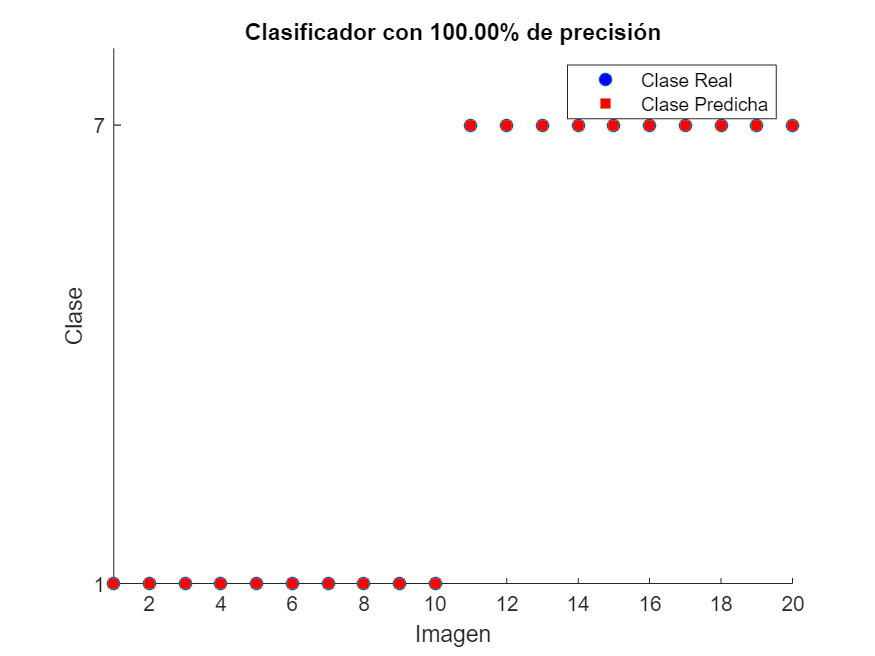

-+-+-+-+-+-+-+-+-+-+-++-+-+-+-+-+-+-+
Las clases = 2 7 
Imagen 7 = {Clase real: 2, Clase predicha: 7}

Imagen 10 = {Clase real: 2, Clase predicha: 7}

El accuracy es = 90 


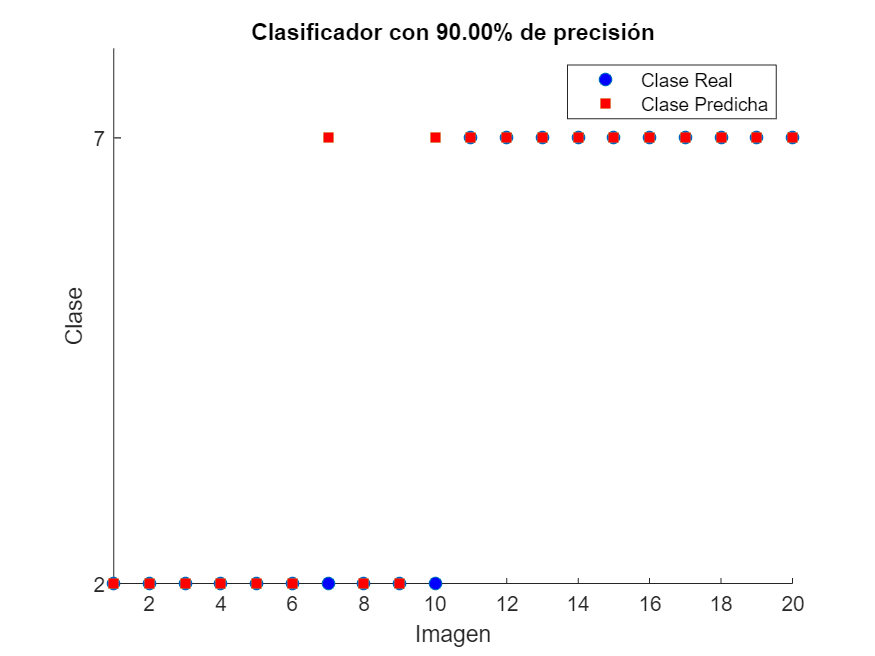

-+-+-+-+-+-+-+-+-+-+-++-+-+-+-+-+-+-+
Las clases = 4 9 
Imagen 2 = {Clase real: 4, Clase predicha: 9}

Imagen 20 = {Clase real: 9, Clase predicha: 4}

El accuracy es = 90 


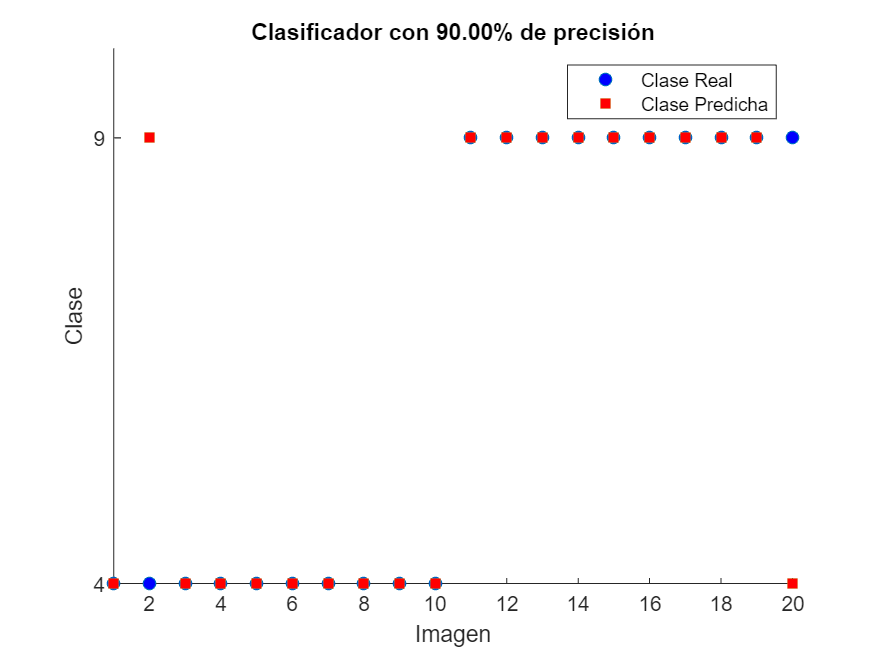

-+-+-+-+-+-+-+-+-+-+-++-+-+-+-+-+-+-+


main1(XTrain, YTrain, XTest, YTest, [80, 20]);

3 Clasificaci´on multiclase MNIST 

Por otro lado, se propone realizar la clasificaci´on multi-clase, es decir, en lugar de utilizar im´agenes de dos clases, utilizar las 10 clases que conforman el dataset. Para ello se deber´a probar: 

(1) La distribuci´on utilizada en la pr´actica anterior (80 im´agenes para train y 20 para test). 

(2) Doblar la distribuci´on (160 para train y 40 para test). Incluir estas dos pruebas en una funci´on main2.m. 


Para las clases = 0 1 2 3 4 5 6 7 8 9 
++++++++++++++++++++++++++++++++++++++++++++
Distribucion Datos => [NumElemTrain = 80, NumElemTest = 20 ]

Imagen 7 = {Clase real: 3, Clase predicha: 2}

Imagen 10 = {Clase real: 4, Clase predicha: 9}

Imagen 13 = {Clase real: 6, Clase predicha: 2}

Imagen 17 = {Clase real: 8, Clase predicha: 5}

Imagen 18 = {Clase real: 8, Clase predicha: 4}

Imagen 19 = {Clase real: 9, Clase predicha: 4}

El accuracy es = 70 


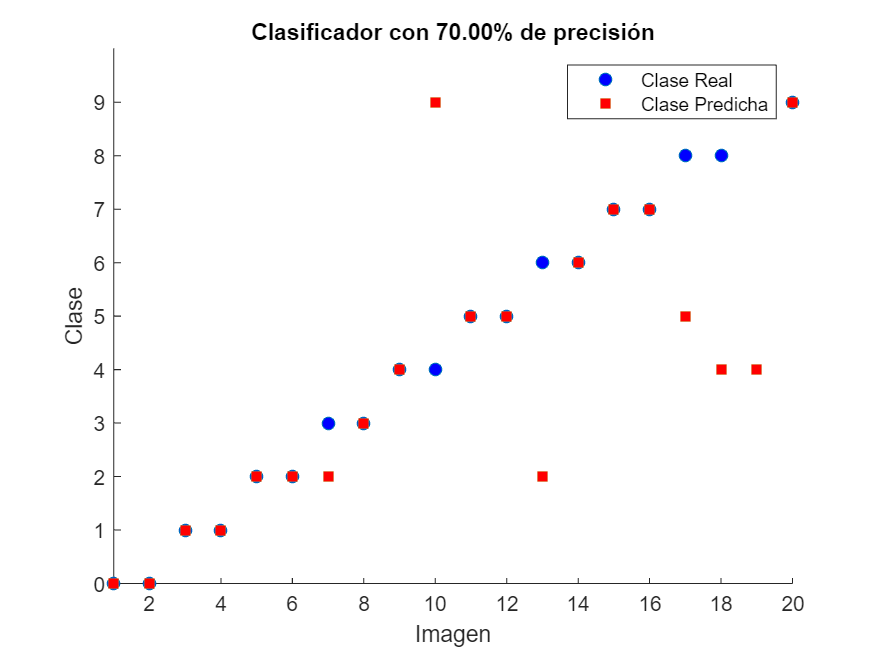

-+-+-+-+-+-+-+-+-+-+-++-+-+-+-+-+-+-+
Distribucion Datos => [NumElemTrain = 160, NumElemTest = 40 ]

Imagen 9 = {Clase real: 2, Clase predicha: 5}

Imagen 11 = {Clase real: 2, Clase predicha: 1}

Imagen 12 = {Clase real: 2, Clase predicha: 1}

Imagen 16 = {Clase real: 3, Clase predicha: 5}

Imagen 18 = {Clase real: 4, Clase predicha: 9}

Imagen 21 = {Clase real: 5, Clase predicha: 2}

Imagen 22 = {Clase real: 5, Clase predicha: 3}

Imagen 24 = {Clase real: 5, Clase predicha: 3}

Imagen 25 = {Clase real: 6, Clase predicha: 2}

Imagen 27 = {Clase real: 6, Clase predicha: 4}

Imagen 33 = {Clase real: 8, Clase predicha: 2}

Imagen 34 = {Clase real: 8, Clase predicha: 4}

Imagen 40 = {Clase real: 9, Clase predicha: 4}

El accuracy es = 6.750000e+01 


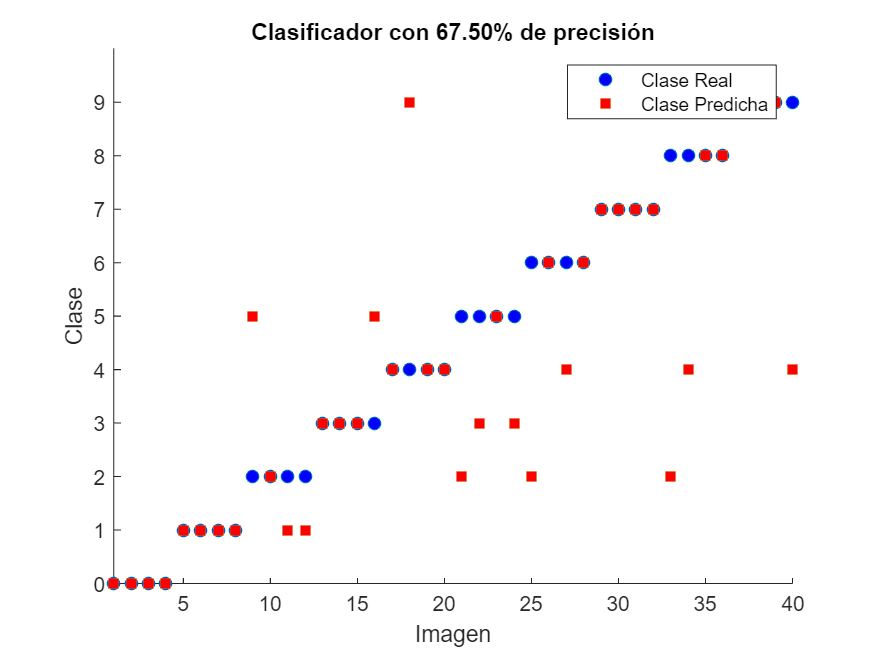

-+-+-+-+-+-+-+-+-+-+-++-+-+-+-+-+-+-+


main2(XTrain, YTrain, XTest, YTest, [80, 20; 160, 40]);

4 Clasificaci´on multiclase EMNIST 

El conjunto de datos EMNIST, es una extensi´on del conjunto MNIST, donde se recogen tambi´en, adem´as de im´agenes de d´ıgitos escritos a mano, letras may´usculas y min´usculas (Figura 2). En este caso, utilizaremos la parte de EMNIST conformada s´olo por letras may´usculas. Originalmente, este conjunto de datos est´a compuesto por 145.600 ejemplos, distribuidos homog´eneamente – como podemos observar en la Figura 1– en 26 clases. Al igual que en la pr´actica anterior utilizaremos una peque˜na parte de este conjunto de datos. Para cargar los datos se suministra un fichero de datos de MATLAB denominado emnist-letters.mat. A partir de ah´ı, con las siguientes lineas de c´odigo obtendremos un mini-conjunto de datos con 1000 im´agenes de entrenamiento y 104 de test (4 para cada clase en test, 4 × 26).

El objetivo de esta parte es obtener una clasificaci´on al igual que en los casos anteriores. Incluir esta prueba en una funci´on main3.m. 


Para las clases = 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 
++++++++++++++++++++++++++++++++++++++++++++
Distribucion Datos => [NumElemTrain = 1000, NumElemTest = 104 ]

Imagen 1 = {Clase real: 1, Clase predicha: 8}

Imagen 2 = {Clase real: 1, Clase predicha: 4}

Imagen 3 = {Clase real: 1, Clase predicha: 15}

Imagen 4 = {Clase real: 1, Clase predicha: 18}

Imagen 5 = {Clase real: 2, Clase predicha: 4}

Imagen 6 = {Clase real: 2, Clase predicha: 14}

Imagen 8 = {Clase real: 2, Clase predicha: 14}

Imagen 9 = {Clase real: 3, Clase predicha: 23}

Imagen 10 = {Clase real: 3, Clase predicha: 1}

Imagen 11 = {Clase real: 3, Clase predicha: 14}

Imagen 12 = {Clase real: 3, Clase predicha: 14}

Imagen 14 = {Clase real: 4, Clase predicha: 18}

Imagen 17 = {Clase real: 5, Clase predicha: 15}

Imagen 18 = {Clase real: 5, Clase predicha: 15}

Imagen 20 = {Clase real: 5, Clase predicha: 15}

Imagen 21 = {Clase real: 6, Clase predicha: 1}

Imagen 22 = {Clase real: 6, Cl

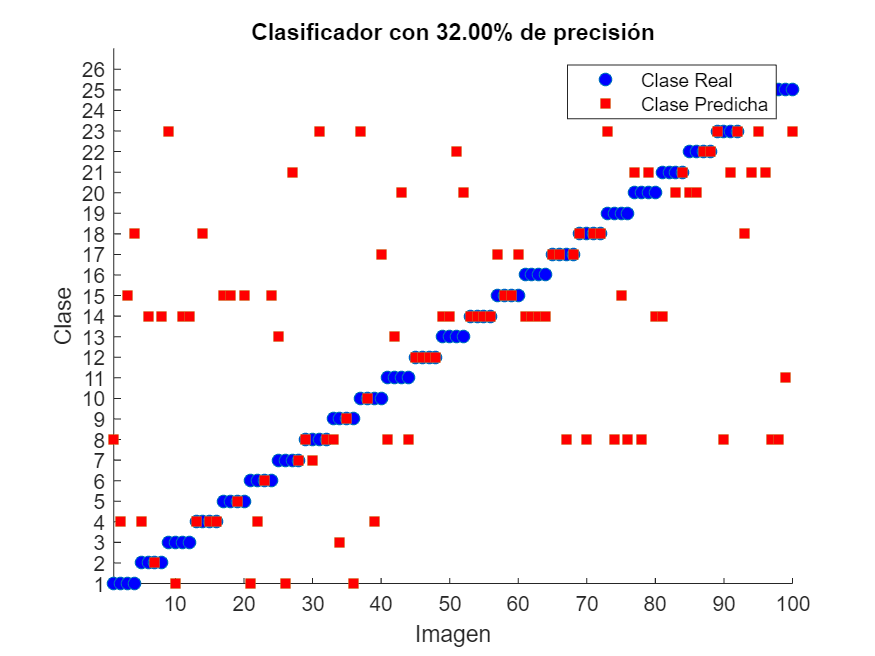

-+-+-+-+-+-+-+-+-+-+-++-+-+-+-+-+-+-+
Distribucion Datos => [NumElemTrain = 2000, NumElemTest = 104 ]

Imagen 1 = {Clase real: 1, Clase predicha: 8}

Imagen 2 = {Clase real: 1, Clase predicha: 4}

Imagen 3 = {Clase real: 1, Clase predicha: 15}

Imagen 4 = {Clase real: 1, Clase predicha: 14}

Imagen 8 = {Clase real: 2, Clase predicha: 14}

Imagen 9 = {Clase real: 3, Clase predicha: 10}

Imagen 10 = {Clase real: 3, Clase predicha: 8}

Imagen 11 = {Clase real: 3, Clase predicha: 2}

Imagen 12 = {Clase real: 3, Clase predicha: 14}

Imagen 14 = {Clase real: 4, Clase predicha: 2}

Imagen 18 = {Clase real: 5, Clase predicha: 15}

Imagen 20 = {Clase real: 5, Clase predicha: 15}

Imagen 21 = {Clase real: 6, Clase predicha: 18}

Imagen 22 = {Clase real: 6, Clase predicha: 4}

Imagen 24 = {Clase real: 6, Clase predicha: 15}

Imagen 25 = {Clase real: 7, Clase predicha: 13}

Imagen 26 = {Clase real: 7, Clase predicha: 1}

Imagen 27 = {Clase real: 7, Clase predicha: 21}

Imagen 30 = {Clase real: 8, 

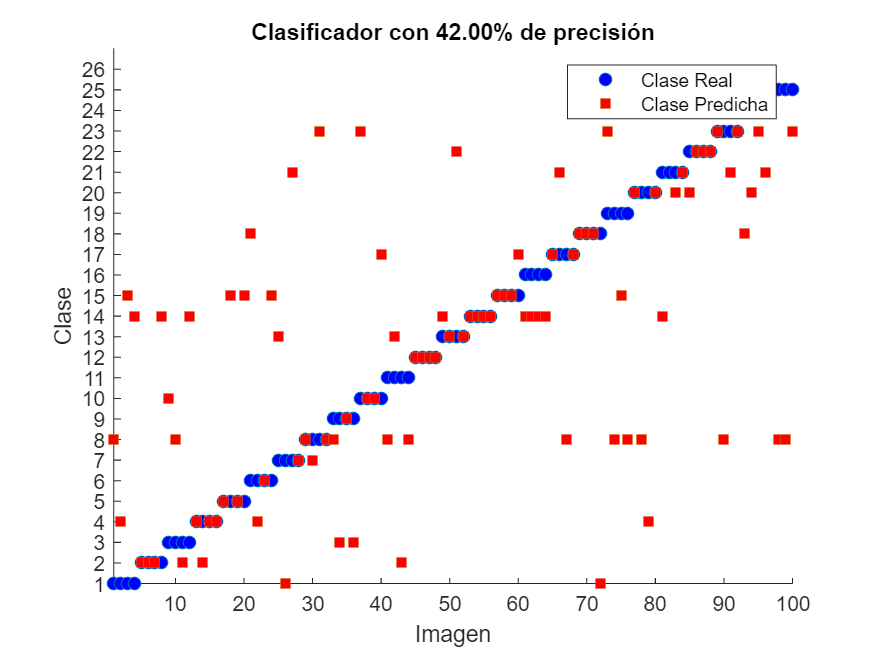

-+-+-+-+-+-+-+-+-+-+-++-+-+-+-+-+-+-+
Distribucion Datos => [NumElemTrain = 5000, NumElemTest = 104 ]

Imagen 1 = {Clase real: 1, Clase predicha: 8}

Imagen 2 = {Clase real: 1, Clase predicha: 4}

Imagen 3 = {Clase real: 1, Clase predicha: 15}

Imagen 4 = {Clase real: 1, Clase predicha: 14}

Imagen 9 = {Clase real: 3, Clase predicha: 23}

Imagen 10 = {Clase real: 3, Clase predicha: 8}

Imagen 11 = {Clase real: 3, Clase predicha: 2}

Imagen 12 = {Clase real: 3, Clase predicha: 14}

Imagen 14 = {Clase real: 4, Clase predicha: 2}

Imagen 18 = {Clase real: 5, Clase predicha: 15}

Imagen 20 = {Clase real: 5, Clase predicha: 15}

Imagen 21 = {Clase real: 6, Clase predicha: 1}

Imagen 22 = {Clase real: 6, Clase predicha: 4}

Imagen 24 = {Clase real: 6, Clase predicha: 15}

Imagen 25 = {Clase real: 7, Clase predicha: 21}

Imagen 27 = {Clase real: 7, Clase predicha: 21}

Imagen 30 = {Clase real: 8, Clase predicha: 7}

Imagen 31 = {Clase real: 8, Clase predicha: 23}

Imagen 33 = {Clase real: 9, 

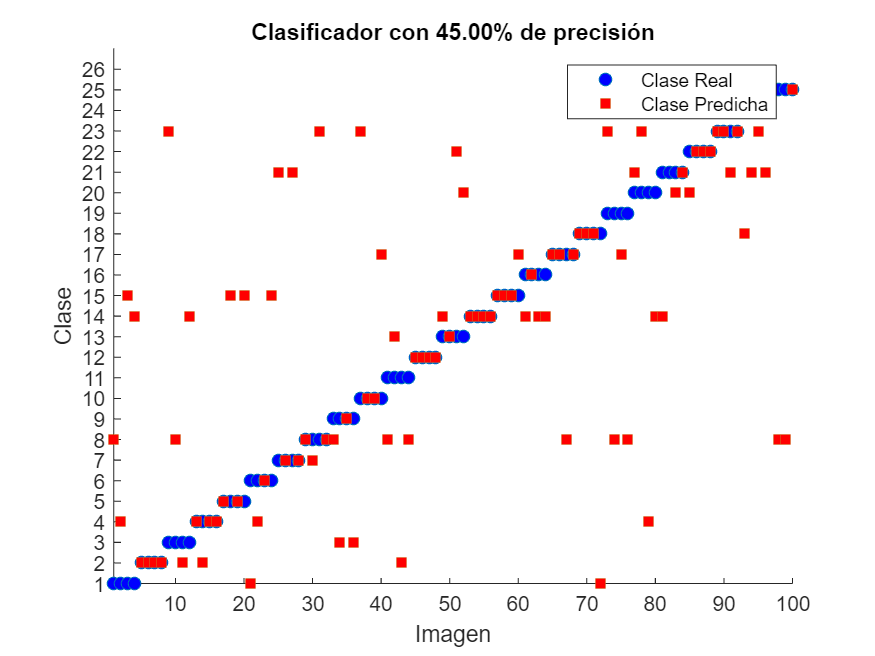

-+-+-+-+-+-+-+-+-+-+-++-+-+-+-+-+-+-+
Distribucion Datos => [NumElemTrain = 10000, NumElemTest = 104 ]

Imagen 1 = {Clase real: 1, Clase predicha: 8}

Imagen 2 = {Clase real: 1, Clase predicha: 4}

Imagen 3 = {Clase real: 1, Clase predicha: 15}

Imagen 4 = {Clase real: 1, Clase predicha: 14}

Imagen 9 = {Clase real: 3, Clase predicha: 23}

Imagen 10 = {Clase real: 3, Clase predicha: 1}

Imagen 11 = {Clase real: 3, Clase predicha: 2}

Imagen 12 = {Clase real: 3, Clase predicha: 14}

Imagen 14 = {Clase real: 4, Clase predicha: 2}

Imagen 18 = {Clase real: 5, Clase predicha: 15}

Imagen 20 = {Clase real: 5, Clase predicha: 15}

Imagen 21 = {Clase real: 6, Clase predicha: 9}

Imagen 22 = {Clase real: 6, Clase predicha: 4}

Imagen 24 = {Clase real: 6, Clase predicha: 15}

Imagen 25 = {Clase real: 7, Clase predicha: 21}

Imagen 27 = {Clase real: 7, Clase predicha: 21}

Imagen 30 = {Clase real: 8, Clase predicha: 7}

Imagen 31 = {Clase real: 8, Clase predicha: 23}

Imagen 33 = {Clase real: 9,

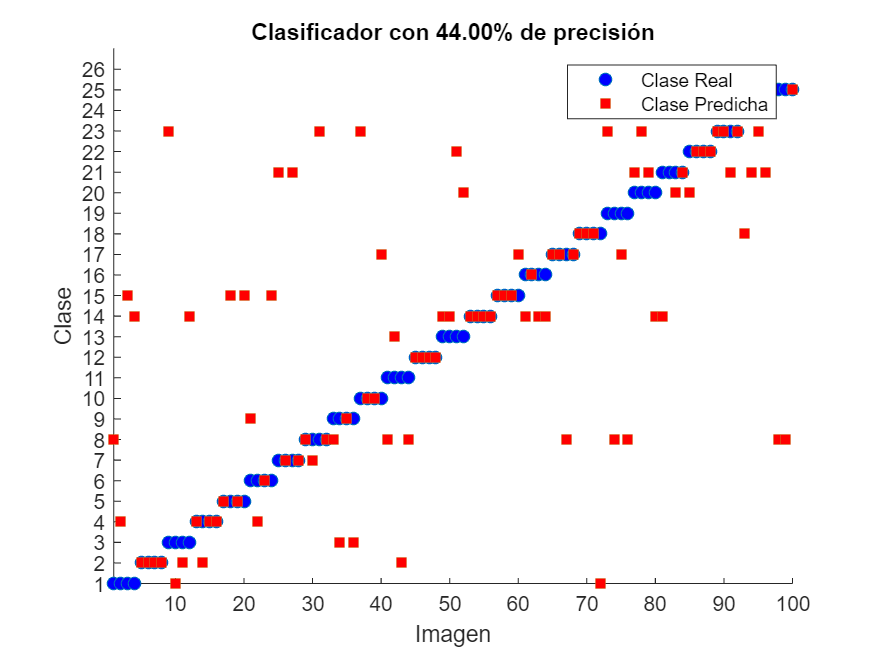

-+-+-+-+-+-+-+-+-+-+-++-+-+-+-+-+-+-+


load('C:/Users/yerso/OneDrive/Escritorio/INGCONOCIMIENTO/Practica1B_PCA/Practica1B_PCA/emnist-letters.mat');
%%N_EX_TRAIN = 1000;
XTr = cast(reshape(dataset.train.images.', 28, 28, 1, []), 'double');
YTr = categorical(dataset.train.labels);
XTe = cast(reshape(dataset.test.images.', 28, 28, 1, []), 'double');
YTe = categorical(dataset.test.labels);
main3(XTr, YTr, XTe, YTe, [1000, 104; 2000, 104; 5000, 104; 10000, 104])